# **Signal and System CA2**

### **Part 2.**

- In this part we are using matlab built-in functions and persian dataset. We're just using different mapset and it has no additional points.

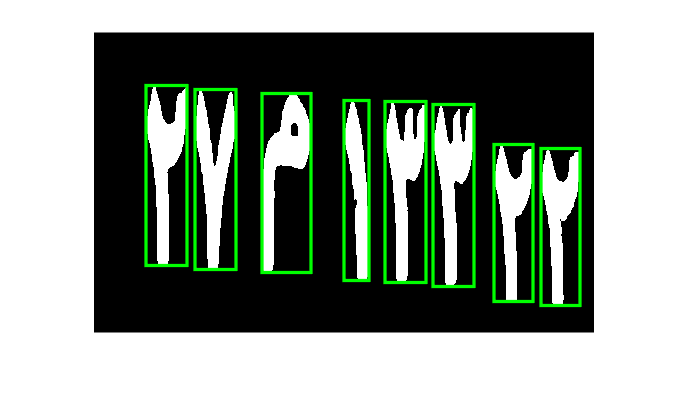

[file, path] = uigetfile({'*.jpg;*.bmp;*.png;*.tif'}, 'Select the image to process.');
source = [path, file];
picture = imread(source);
picture = imresize(picture,[300 500]);
picture = myGrayFunc(picture);
threshold = graythresh(picture);
picture = ~myBinaryFunc(picture, threshold);
minPixelComp = 450;
picture = bwareaopen(picture, minPixelComp); 
minPixelBackground = 3800;
background = bwareaopen(picture, minPixelBackground);

picture = picture - background;
[labeledComponents, numOfComps] = bwlabel(picture);
propied = regionprops(labeledComponents,'BoundingBox');
figure;
imshow(picture);
hold on
for n=1:size(propied, 1)
    rectangle('Position',propied(n).BoundingBox, 'EdgeColor','g','LineWidth',2)
end
hold off

DATASET_FOLDER = 'Persian Map Set';
contents = {dir(DATASET_FOLDER).name};
files = contents(3:end);

characters = cell(2, length(files));

for i = 1:length(files)
    c2m = cell2mat(files(i));
    characters(1, i) = {imread([DATASET_FOLDER, '\', c2m])};
    characters(2, i) = {c2m(1:find(c2m == '.') - 1)};
end
save("PersianCharacters.mat", 'characters');
final_output=[];
t = [];
for n = 1 : numOfComps
    [r, c] = find(labeledComponents==n);
    Y = picture(min(r):max(r), min(c):max(c));
    Y = imresize(Y, [100,80]);
    
    ro = zeros(1,size(characters, 2));
    for k = 1 : size(characters, 2)   
        characters{1, k} = imresize(characters{1, k}, [100, 80]);
        ro(k) = corr2(characters{1,k},Y);
    end
    
    [MAXRO, pos] = max(ro);
    if MAXRO > .5
        out = cell2mat(characters(2, pos));       
        final_output = [final_output out];
    end
end

file = fopen('persian_plate.txt', 'wt');
fprintf(file,'%s\n',final_output);
fclose(file);
final_output

final_output = '۲۷م۱۳۳۲۲'